# MTF analysis of coded exposure deblurring

## param

M = 32; % sequence length
N = 128; % FFT length

## 1d fft

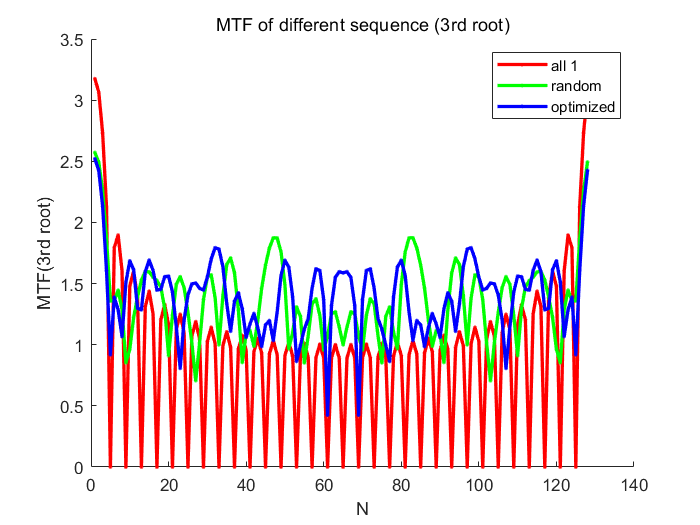

figure,hold on,title('MTF of different sequence (3rd root)')
% all a
sq = ones(1,M);
sq_fft = fft(sq,N);
sq_fft_mtf = abs(sq_fft);
plot(1:N,nthroot(sq_fft_mtf,3),'r.-','LineWidth',2)

% random
sq = single(randn(1,M)>0.5);
sq_fft = fft(sq,N);
sq_fft_mtf = abs(sq_fft);
plot(1:N,nthroot(sq_fft_mtf,3),'g.-','LineWidth',2)

% optimized
sq = [1 0 1 1 1 0 0 0 1 0 1 1 0 0 0 1 1 0 1 1 1 0 0 0 1 0 0 0 1 1 0 1];
sq_fft = fft(sq,N);
sq_fft_mtf = abs(sq_fft);
plot(1:N,nthroot(sq_fft_mtf,3),'b.-','LineWidth',2)

xlabel('N'),ylabel('MTF(3rd root)')
legend('all 1','random','optimized')

## 2d fft2

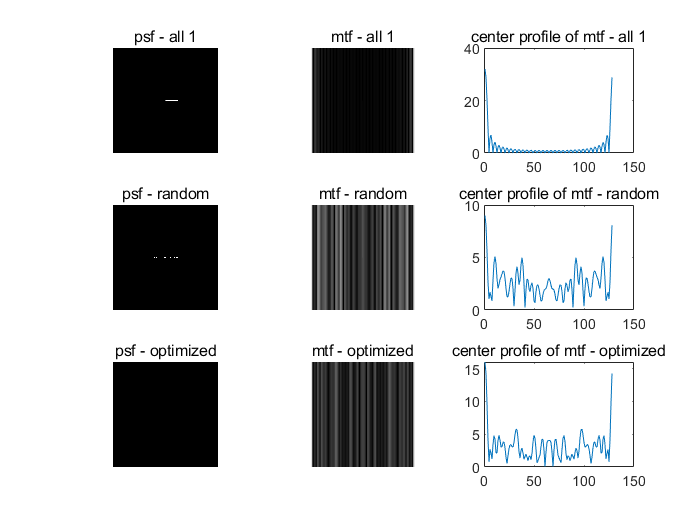

figure, title('MTF of 2d psf from different sequences')
psf = zeros(N,N);
psf_pos = floor((N-M)/2):floor((N-M)/2)+31;

% all 1
sq = ones(1,M);
psf(floor(N/2),psf_pos) = sq;
mtf=abs(fft2(psf));
subplot(331),imshow(psf,[]),title('psf - all 1')
subplot(332),imshow(mtf,[]),title('mtf - all 1')
subplot(333),plot(mtf(floor(M/2),:)),title('center profile of mtf - all 1')

% random
sq = single(randn(1,M)>0.5);
psf(floor(N/2),psf_pos) = sq;
mtf=abs(fft2(psf));
subplot(334),imshow(psf,[]),title('psf - random')
subplot(335),imshow(mtf,[]),title('mtf - random')
subplot(336),plot(mtf(floor(M/2),:)),title('center profile of mtf - random')

% optimized
sq = [1 0 1 1 1 0 0 0 1 0 1 1 0 0 0 1 1 0 1 1 1 0 0 0 1 0 0 0 1 1 0 1];
psf(floor(N/2),psf_pos) = sq;
mtf=abs(fft2(psf));
subplot(337),imshow(psf,[]),title('psf - optimized')
subplot(338),imshow(mtf,[]),title('mtf - optimized')
subplot(339),plot(mtf(floor(M/2),:)),title('center profile of mtf - optimized')